# Estudio de la caida en la conexion PP entre Alemania y España

EN EL PESO X=39 SE DETECTA UN SALTO QUE PUEDE VENIR DE UN ERROR NUMERICO DE MATLAB. INVESTIGUEMOSLO

load("MatricesSparse.mat")
load("Analisis_GC.mat")
load("Data_CGs.mat")
load("Nodos.mat")
load("Var_Archivo_3_TFG.mat")
load("Variables_Arch_2_TFG.mat")

## **Conexion entre CG de Alemania y España  AE**

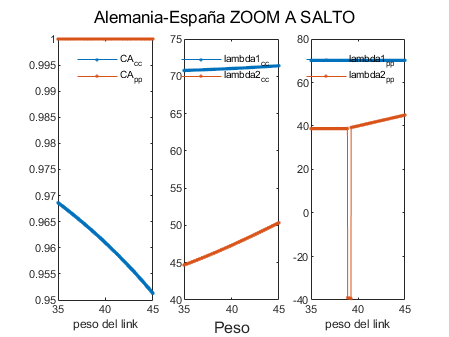

% [Mat_AE,Mat_AE_CC,Mat_AE_PP,CA_AE_CC,aut1_AE_CC,aut2_AE_CC,CA_AE_PP,aut1_AE_PP,aut2_AE_PP] = ...
% analisis_conexion_GC(adj_GC_A,adj_GC_E,1,Central_node_A,Peripheral_node_A,Central_node_E,Peripheral_node_E);
minpeso = 35;
maxpeso = 45;
intervalo = 0.025; %  TAMAÑO DEL "GRID" 

plotCA_AE_CC = []; plotaut1_AE_CC = []; plotaut2_AE_CC = [];
plotCA_AE_PP = []; plotaut1_AE_PP = []; plotaut2_AE_PP = [];
for i = minpeso:intervalo:maxpeso
    [Mat_b1_b2,Mat_b1_b2CC,Mat_b1_b2PP,CA_CC,aut1_CC,aut2_CC,CA_PP,aut1_PP,aut2_PP] = ...
    analisis_conexion_GC(adj_GC_A,adj_GC_E,i,Central_node_A,Peripheral_node_A,Central_node_E,Peripheral_node_E);
    plotCA_AE_CC = [plotCA_AE_CC CA_CC];
    plotaut1_AE_CC = [plotaut1_AE_CC aut1_CC];
    plotaut2_AE_CC = [plotaut2_AE_CC aut2_CC];
    plotCA_AE_PP = [plotCA_AE_PP CA_PP];
    plotaut1_AE_PP = [plotaut1_AE_PP aut1_PP];
    plotaut2_AE_PP = [plotaut2_AE_PP aut2_PP];
end

figure
subplot(1,3,1)
plot(minpeso:intervalo:maxpeso,plotCA_AE_CC,'.-')
hold on
plot(minpeso:intervalo:maxpeso,plotCA_AE_PP,'.-')
xlabel('ω')
legend({'CA_{cc}','CA_{pp}'},...
    'Location','northeast','Box','off');   
hold off

subplot(1,3,2)
plot(minpeso:intervalo:maxpeso,plotaut1_AE_CC,'.-')
hold on
plot(minpeso:intervalo:maxpeso,plotaut2_AE_CC,'.-')
xlabel('ω','FontSize',12)
legend({'lambda1_{cc}','lambda2_{cc}'},...
    'Location','northeast','Box','off');   
hold off

subplot(1,3,3)
plot(minpeso:intervalo:maxpeso,plotaut1_AE_PP,'.-')
hold on
plot(minpeso:intervalo:maxpeso,plotaut2_AE_PP,'.-')
xlabel('ω')
legend({'lambda1_{pp}','lambda2_{pp}'},...
    'Location','northeast','Box','off');   
hold off
sgtitle('Alemania-España ZOOM A SALTO')

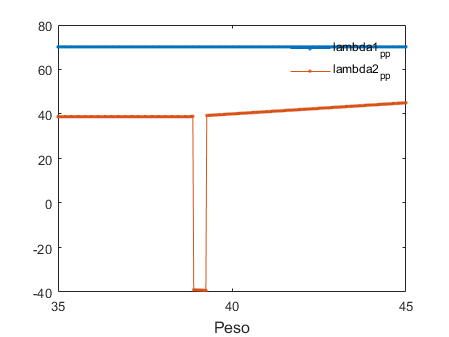

figure
plot(minpeso:intervalo:maxpeso,plotaut1_AE_PP,'.-')
hold on
plot(minpeso:intervalo:maxpeso,plotaut2_AE_PP,'.-')
xlabel('ω','FontSize',12)
legend({'lambda1_{pp}','lambda2_{pp}'},...
    'Location','northeast','Box','off');   
hold off